# MAT-63506 Scientific computing, Solutions for exercise set 3,

# Mar 19 - 25, 2018

## Exercise 1

Form the indices of the sequence and the sequence itself. We use elementwise operations in forming `xn`, since `n` is a vector.

n = 1:50;
xn = cos((-1).^n.*n) + sin(n.^2);

Plot the sequence and add axis labels and title. Normally the $y$-axis label is rotated by 90-degrees. Setting the `Rotation`-property to 0 prevents the rotation.

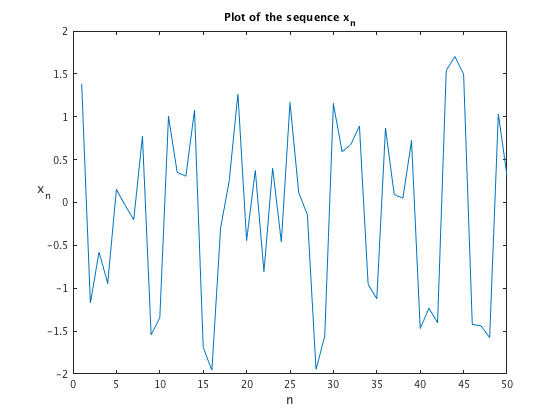

figure(1), plot(n, xn)
xlabel('n', 'Fontsize', 12)
ylabel('x_n', 'Rotation', 0, 'Fontsize', 12)
title('Plot of the sequence x_n')

Make a stem, stairs, and bar plot of `xn`.

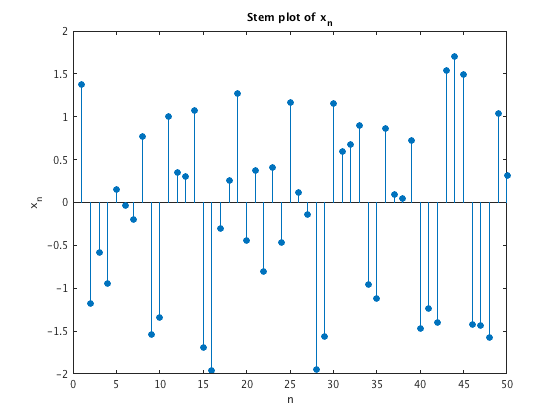

stem(n, xn, 'filled')
xlabel('n'); ylabel('x_n'); title('Stem plot of x_n')

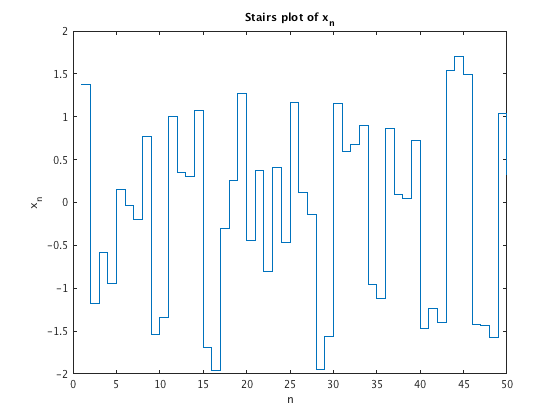

stairs(n, xn)
xlabel('n'); ylabel('x_n'); title('Stairs plot of x_n')

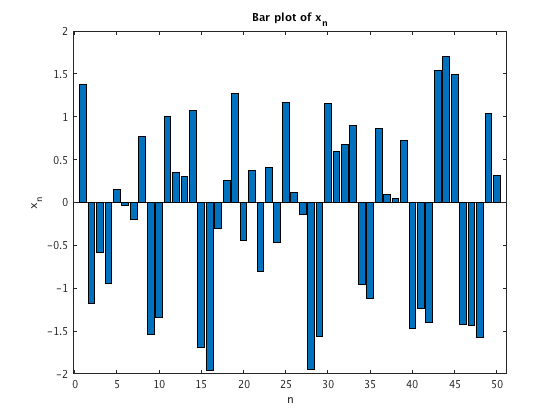

bar(n, xn)
xlabel('n'); ylabel('x_n'); title('Bar plot of x_n')

## Exercise 2

Form a matrix `J` whose rows are $J_\nu(x)$. We preallocate storage for `J` and the legend strings `strs`, otherwise Matlab warns that they change size in every loop iteration. We use the catenation operator `[]` to construct each legend string. Notice that we have to enclose the subscripts with braces.

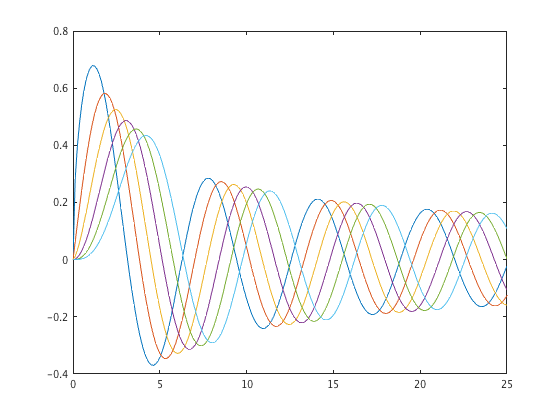


clf
x = linspace(0, 25, 200);
nu = 0.5:0.5:3;
J = zeros(length(nu), length(x));  % Preallocate storage for J
strs = cell(size(nu)); % Preallocate storage for the legend strings
for k = 1:length(nu)
    J(k, :) = besselj(nu(k), x);  % Form J row by row
    strs{k} = ['$J_{' num2str(nu(k)) '}(x)$'];
end
plot(x, J)

Add axis labels

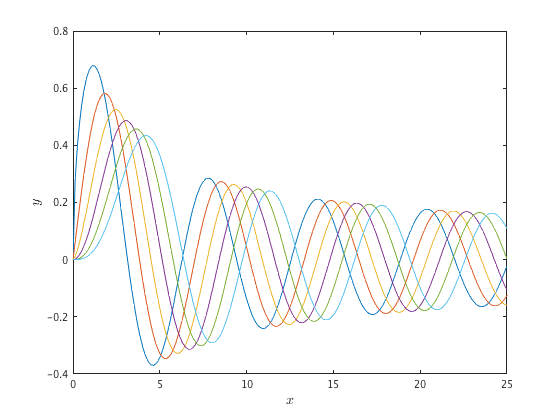

xlabel('$x$', 'Interpreter', 'latex', 'Fontsize', 14)
ylabel('$y$', 'Interpreter', 'latex', 'Fontsize', 14)

Add a title and the legend

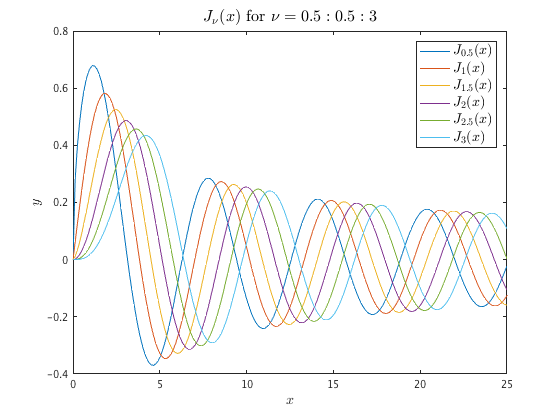

title('$J_\nu(x)$ for $\nu=0.5:0.5:3$', 'Interpreter', 'latex',...
	'FontSize', 16)
legend(strs, 'Interpreter', 'latex', 'FontSize', 14)

## Exercise 3

Form the `x` vector, `k`, and `t`.

x = 0:0.01:5;
k = 1.4;
t = sqrt(1 - 1/k^2);

Compute $|R|$.

Rnum = (1 + t)*(1 + sqrt(t))^2*x.^4 - 2*(1 + t)*(1 + sqrt(t))*x.^2 + 1;
Rden = (1 + t)*(1 - sqrt(t))^2*x.^4 - 2*(1 + t)*(1 - sqrt(t))*x.^2 + 1;
R = abs(Rnum./Rden);

Plot $|R|$. The first plot is with linear `x`- and `y`-axes. The second plot is with logarithmic `x`- and `y`-axes. The third plot is with logarithmic `x`-axis and linear `y`-axes. The fourth plot is with linear `x`-axis and logarithmic `y`-axes.

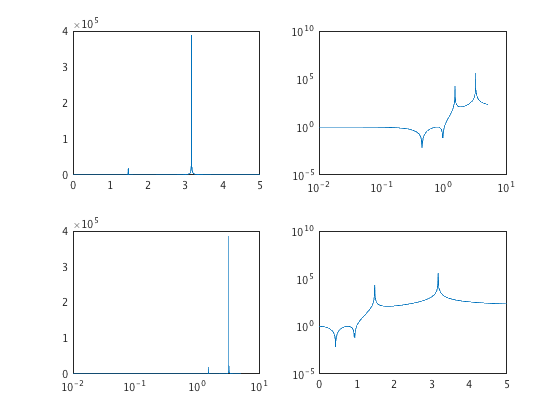

subplot(221), plot(x, R)
subplot(222), loglog(x, R)
subplot(223), semilogx(x, R)
subplot(224), semilogy(x, R)

## Exercise 4

Form the parameter vector t.

t = 0:0.01:2*pi;

Compute the corresponding x and y values.

xt = sin(t).*(exp(cos(t)) - 2*cos(4*t) - sin(t/12).^5);
yt = cos(t).*(exp(cos(t)) - 2*cos(4*t) - sin(t/12).^5);

Plot the parametrized curve and add axes labels.

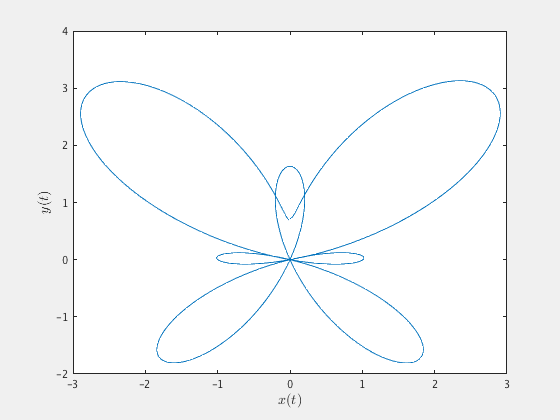

plot(xt, yt)
xlabel('$x(t)$', 'Interpreter', 'latex', 'FontSize', 14)
ylabel('$y(t)$', 'Interpreter', 'latex', 'FontSize', 14)

## Exercise 5

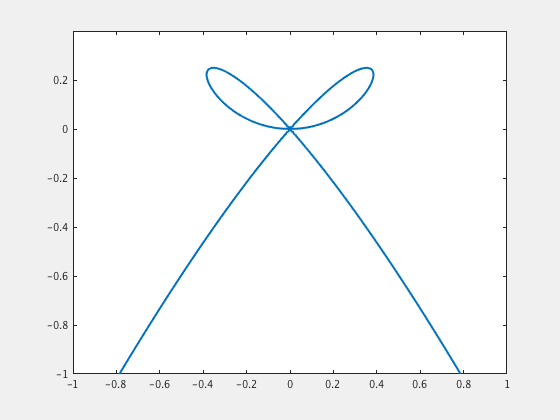

h =   ImplicitFunctionLine with properties:

     Function: @(x,y)x.^4-x.^2.*y+y.^3
       XRange: [-1 1]
       YRange: [-1 0.4000]
        Color: [0 0.4470 0.7410]
    LineStyle: '-'
    LineWidth: 2

  Show all properties


figure('Visible', 'on')
cmh = uicontextmenu;
uimenu(cmh,'Text', 'Red', 'MenuSelectedFcn', {@setColor, 'r'});
uimenu(cmh,'Text', 'Green', 'MenuSelectedFcn', {@setColor, 'g'});
uimenu(cmh,'Text', 'Black', 'MenuSelectedFcn', {@setColor, 'k'});

h = fimplicit(@(x,y) x.^4 - x.^2.*y + y.^3, [-1 1 -1 0.4], 'lineWidth', 2)

h.UIContextMenu = cmh;

## Exercise 6

Plot the curves and store a handle to them in `h`.

h =   2×1 Line array:

  Line
  Line


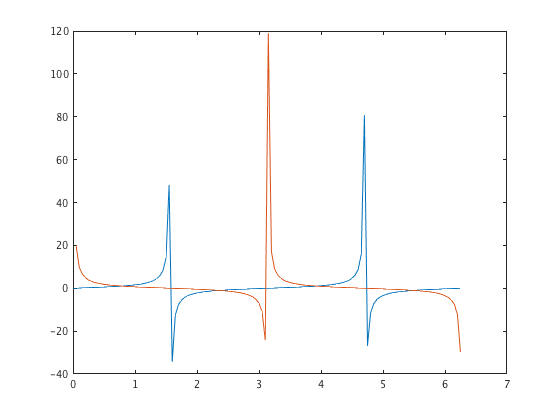

x = 0:0.05:2*pi;
h = plot(x, tan(x), x, cot(x))

1. Find the indices of `y`-values with $|y| > 8$ and replace the corresponding elements with `NaN`.

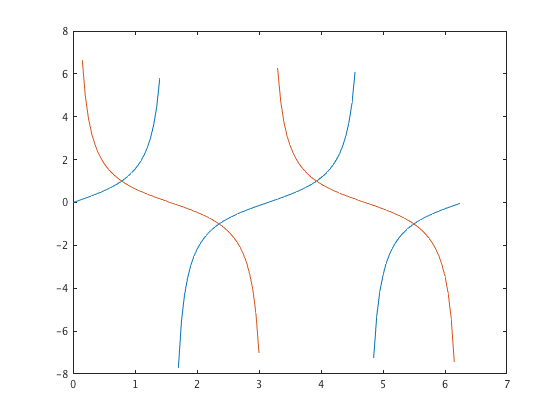

ind1 = abs(h(1).YData) > 8;
ind2 = abs(h(2).YData) > 8;

h(1).YData(ind1) = NaN;
h(2).YData(ind2) = NaN;

2. Set `x`-ticks and `x`-tick labels. The tick labels show the symbol $\pi$ correctly only in version 2014b and later.

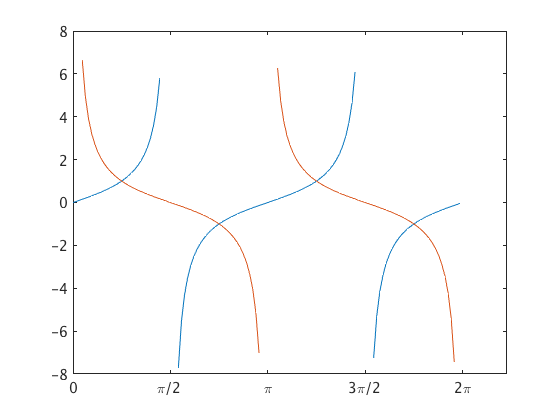

set(gca, 'XTick', (0:4)*pi/2)
set(gca, 'XTickLabel', {'0', '\pi/2', '\pi', '3\pi/2', '2\pi'},...
    'FontSize', 14)

3. Set axis labels. We get two lines of text for `ylabel` by using a 2x1 cell array of strings. We also change the position of the label so that it doesn't overlap the `YTickLabels`.

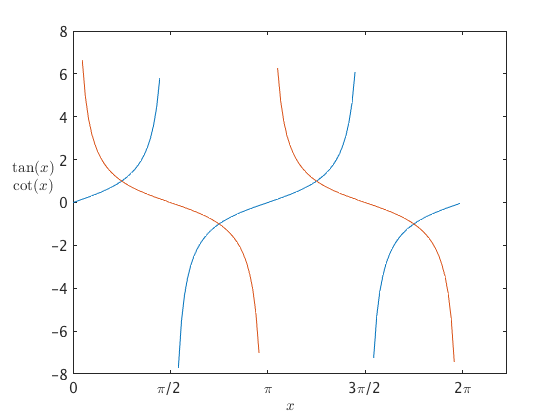

xlabel('$x$', 'Interpreter', 'latex', 'Fontsize', 16)
ylabel({'$\tan(x)$ '; '$\cot(x)$ '}, 'Interpreter', 'latex',...
	'Fontsize', 16, 'Rotation', 0, 'Position', [-0.6 0.3])

4. Set markers and their size and colors.

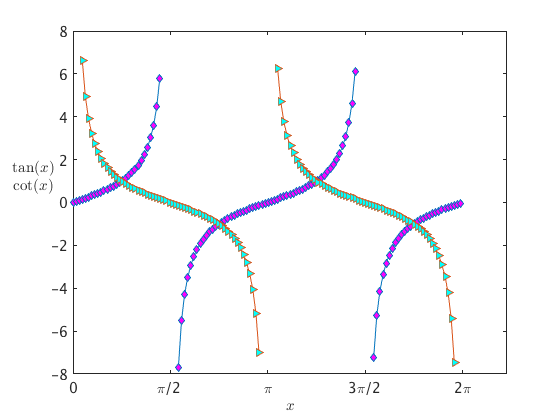

set(h, {'Marker', 'MarkerSize', 'MarkerFaceColor'},...
	{'d', 6, 'm'; '>', 7, 'c'})

function setColor(~, ~, c) % We don't need the first two arguments
    % Callback function for the uimenus
    
    h = gco; % Get the current object
    h.Color = c;
end